# Représentation des modes LP d'une fibre optique à saut d'indice

## Objectifs

Le but de ce TP de simulation est de représenter, à l'aide de Matlab, les distributions de champ ou d'intensité des modes linéairement polarisés (modes LP) d'une fibre optique à saut d'indice sous l'hypothèse du guidage faible.

De telles représentations sont fréquemment données dans le chapitre 6 du polycopié de cours, dont on utilisera un certain nombre de résultats. 

Ici, vous allez vous-mêmes représenter les distributions scalaires $\psi_{lm}\left(r,\theta\right)$ des modes LP$$_{lm}$$, où $l \geq 0$ et $m \geq 1$ sont des entiers.

## Prise en main

### Les Live scripts de Matlab

Cet exercice utilise la fonctionnalité Live script de Matlab, qui permet de combiner harmonieusement du texte formaté et du code exécutable, à la manière des notebooks Jupyter que vous connaissez peut-être déjà en Python. 

Vous pourrez trouver plus d'information sur les Live scripts en suivant le lien :

[https://fr.mathworks.com/help/matlab/live-scripts-and-functions.html](https://fr.mathworks.com/help/matlab/live-scripts-and-functions.html)

Ce problème est constitué d'un unique fichier Live script. Il vous sera demandé de le compléter avec votre propre code et de discuter et commenter vos résultats directement dans le fichier.

En conséquence, ce n'est peut-être pas une bonne idée d'essayer d'exécuter l'ensemble du script. Des sections ont été définies dans le script (et vous êtes invités à définir vos propres sections selon vos besoins : voir le menu du Live editor ci-dessus).

Vous êtes invités à exécuter séquentiellement les différentes sections (tout du moins celles dans lesquelles du code figure).

Vous pourrez toujours effacer au besoin des variables dans la fenêtre de commande de Matlab ou exécuter le Live script à nouveau depuis le début.

Vous pouvez aussi effacer les résultats de calcul et les graphes générés par le Live script (par exemple  `right click > Clear all output`).

Comme à l'accoutumée vous devrez lire le texte avec la plus grande attention. Je sais que je peux compter sur vous.

Les questions auxquelles il vous est demandé de répondre seront formatées *en italique*.

Vos réponses, commentaires, interprétations des résultats seront formatés en **caractères gras**. Vous pouvez réaliser cette mise en forme en utilisant le menu du Live editor, ou simplement en saisissant votre texte entre des astérisques doubles. Ainsi **ceci sera formaté en gras** mettra automatiquement le texte en forme selon **ceci sera formaté en gras**.

Pour d'autres éléments de mise en forme du texte : [https://fr.mathworks.com/help/matlab/matlab_prog/format-live-scripts.html](https://fr.mathworks.com/help/matlab/matlab_prog/format-live-scripts.html)

Avant de démarrer l'étude proprement dite, nous allons procéder à un rapide test de la fonctionnalité des Live scripts.

*Question : *

Représenter la fonction $y = x^2$ for $x\in \left[-5,5\right]$

Vous pouvez insérer du code Matlab (`Insert > Code`)

x = linspace(-5,5,100);
y = x.^2;
figure('Name','the stupid figure I am asked to plot')
plot(x,y,'b-')
xlabel('x')
ylabel('y')

Vous pouvez maintenant exécuter ce bloc de code (`Run Section` ou `CTRL + ENTER`).

Le code sera exécuté dans toute la section. Dans le cas présent, il n'y a qu'un seul bloc de code dans la section. La section est délimitée par des lignes bleues horizontales dans le Live Script et des rayures bleues dans la marge de gauche.

Si vous exécutez maintenant la section présente, le graphe apparaîtra dans le panneau de droite.

Il vous appartiendra de définir des sections afin que le code puisse s'exécuter harmonieusement (résultat par résultat, graphe par graphe pour les visualisations).

Vous pourrez aussi faire apparaître le graphe en ligne avec le texte (Marge de droite > `Show outputs inline`), ce qui sera plus aisé afin d'organiser vos graphiques par la suite et les faire apparaître dans le bon ordre par rapport à vos blocs de code et autres commentaires.

Vous pouvez maintenant effacer le graphe produit dans cette section qui, avouons-le, n'est pas d'un très grand intérêt. Pour cela, effectuer dans le panneau  de droite : `Right click > Clear all output` ou `Right click > Clear output` 

Quelques raccourcis utiles :

- Exécuter le code présent dans une section (entre deux séparations horizontales) : `CTRL + ENTER`

- Insérer un séparateur de sections : `CTRL + ALT + ENTER`

- Alterner la saisie, d'un bloc de texte avec un bloc de code, ou l'inverse : `ALT + ENTER`

Il est également possible de définir des fonctions Matlab dans un Live script. Cependant, **ces fonctions devront obligatoirement être définies à la fin du script**. En conséquence, une section intitulée Vos fonctions a été créée afin que vous puissiez y définir autant de fonctions que vous le jugez nécessaire. Il vous appartient de deviner où cette section a été créée.

### Structure de l'archive

Le texte de cet exercice est également disponible dans un dépôt GitHub dont le lien vous a été communiqué.

Ce dépôt est organisé comme suit :

- `src` contient des fonctions Matlab qui vous seront utiles pour la partie de l'exercice concernant les fibres monomodes (calcul de l'indice de réfraction de la silice, calcul de dérivées par différences finies, calcul d'intégrales doubles par la méthode de Simpson, etc.). Vous aurez besoin d'utiliser ces fonctions, décrites (entrées, sorties, etc) dans leurs préambules.

- `libs` contient des bibliothèques externes (mises à disposition par leurs auteurs respectifs, sous licence open source) qui sont utilisées par certaines fonctions dans `src`. Vous n'avez pas besoin, en principe, de prendre connaissance du contenu du répertoire `libs`.

Vous pouvez directement télécharger le dépôt depuis site GitHub (voir ci-dessous) ou bien, si vous disposez du logiciel Git, le cloner.

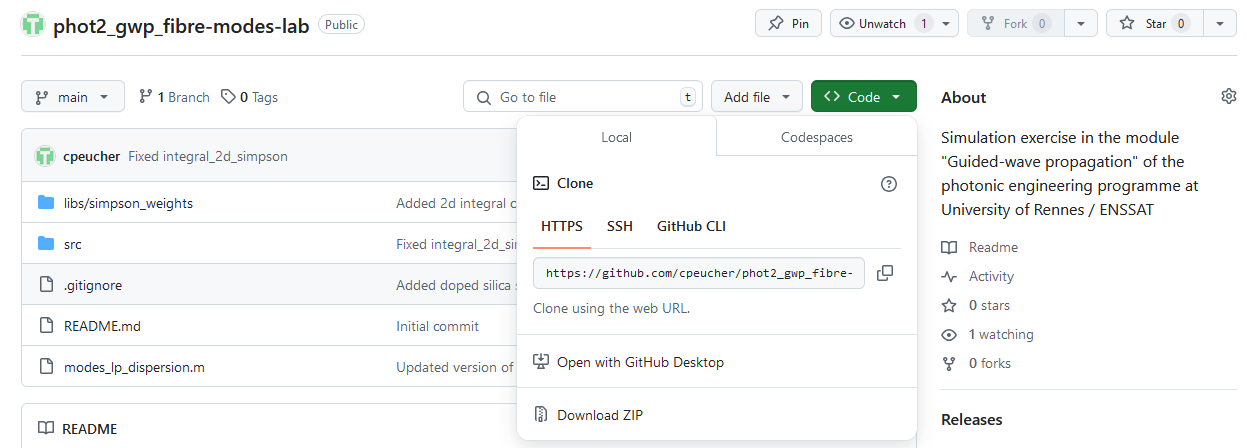

N'oubliez pas d'ajouter le répertoire de l'archive aux chemins connus de Matlab (afin que ce dernier puisse localiser les fonctions) : depuis la fenêtre principale Matlab `Home > Set Path > Add with Subfolders` et pointer vers le répertoire dans lequel l'archive a été extraite / où le dépôt a été cloné.

## Quelques rappels théoriques

On considère dans ce qui suit une fibre optique à saut d'indice consistant en un cœur formé d'un cylindre de révolution de rayon $a\;$et d'indice de réfraction $n_1$ entouré d'une gaine d'indice de réfraction $n_2$ dont les dimensions transverses sont bien plus grandes que celles du cœur. On notera


$$\Delta = \frac{n_1^2 - n_2^2}{2 n_1^2}$$


le paramètre de guidage.

On se placera sous l'hypothèse du guidage faible pour laquelle $n_1 \approx n_2$.

Avec ces hypothèses, il a été démontré dans le cours que la distribution transverse du champ du mode scalaire LP$$_{lm}$$ s'écrit, dans un système de coordonnées polaires $ $\left(r,\theta\right)$$


$$\psi_{lm}\left(r,\theta\right) =
  \begin{cases}
    J_l\left(\kappa_{lm} r\right)\begin{cases}
                              \cos\left(l\theta\right) \\
                              \sin\left(l\theta\right)
                            \end{cases} & \mbox{si } r \leq a, \\
    \frac{J_1\left(\kappa_{lm} a\right)}{K_l\left(\gamma_{lm} a\right)} K_l\left(\gamma_{lm} r\right)\begin{cases}
                                                                                        \cos\left(l\theta\right) \\
                                                                                        \sin\left(l\theta\right)
                                                                                      \end{cases} & \mbox{si } r > a.
  \end{cases}$$


où la solution en $$\cos\left(l\theta\right)$$ correspond à un mode pair et celle en $$\sin\left(l\theta\right)$$  à un mode impair. $$J_l\left(x\right)$$ est la fonction de Bessel de première espèce d'ordre $$l$$ et $$K_l\left(x\right)$$ est la fonction de Bessel modifiée de deuxième espèce d'ordre $$l$$. On observera que le champ dans l'équation ci-dessus est défini à une constante multiplicative près (en d'autres termes, on a le choix de la puissance du mode) et que la continuité du champ en $$r=a$$ est bien assurée.

Les coefficients $$\kappa_{lm}$$ et $$\gamma_{lm}$$ sont liés aux variables normalisées $$u_{lm}$$ et $$v_{lm}$$ selon


$$u_{lm} = \kappa_{lm} a,$$


$v_{lm} = \gamma_{lm} a$,

qui vérifient, pour tous les modes LP$$_{lm}$$,


$$u_{lm}^2 + v_{lm}^2 = V^2,$$


où


$$V = \frac{2\pi a}{\lambda}\sqrt{n_1^2 - n_2^2}$$


est la fréquence normalisée, $$\lambda$$ étant la longueur d'onde dans le vide.

Il a également été montré dans le cours que $u_{lm}$ et $v_{lm}$ s'expriment en fonction de la constante de propagation normalisée du mode $b_{lm}$ selon


$$b_{lm} = \frac{v_{lm}^2}{V^2} = 1 - \frac{u_{lm}^2}{V^2}.$$


Pour une fréquence normalisée (c'est-à-dire pour une fibre donnée, totalement définie par $n_1$, $n_2$ et $a$, et à une longueur d'onde donnée.) $V$ et un ordre azimutal $l \geq 0$ donnés, la constant de propagation normalisée $b_{lm}$ du mode LP$$_{lm}$$ est la $$m-$$ème racine de l'équation de dispersion, dans l'ordre des valeurs de $b$ décroissantes.


$$V \sqrt{1-b}\;\frac{J_{l-1}\left(V\sqrt{1-b}\right)}{J_l\left(V\sqrt{1-b}\right)} = - V \sqrt{b}\;\frac{K_{l-1}\left(V\sqrt{b}\right)}{K_l\left(V\sqrt{b}\right)}.$$


Pour rappel, la constante de propagation normalisée est définie selon


$$b_{lm} = \frac{n_{\mathrm{eff},lm}^2 - n_2^2}{n_1^2 - n_2^2},$$


où $n_{\mathrm{eff},lm}$ est l'indice effectif du mode. Elle est telle que $0 \leq b_{lm} \leq 1$, $b_{lm} = 0$ correspondant à la coupure du mode (fréquence minimale pour laquelle le mode existe).

Afin de représenter la distribution en champ ($$\psi_{lm}\left(r,\theta\right)$$) ou en intensité ($$\left|\psi_{lm}\left(r,\theta\right)\right|^2$$) d'un mode LP$$_{lm}$$ donné, il faudra donc d'abord déterminer sa constante de propagation normalisée $b_{lm}$ en cherchant les racines de l'équation de dispersion, puis en déduire $\kappa_{lm}$ et $\gamma_{lm}$  avant de pouvoir utiliser les expressions du champ.

Avant de démarrer, nous faisons le petit ménage habituel

clear all
close all

## Représentation des modes

On considère dans ce qui suit une fibre à saut d'indice dont les paramètres sont

- $$a = 30$$ $\mu$m

- 
$$$n_1 = 1,5$$$


- 
$$$\Delta = 0,001$$$


Cette fibre sera utilisée à la longueur d'onde $\lambda = 1550$ nm.

On peut donc définir les variables Matlab :

a = 30e-6;
% Fibre radius, in m
n1 = 1.5;
% Refractive index of the core.
Delta = 0.001;
% Relative refractive index difference.

### Résolution de l'équation de dispersion

*Calculer la fréquence normalisée *$V$.

% SAISIR VOTRE CODE ICI

*D'après le cours, combien de modes (hors dégénérescences mode pair / mode impair et de polarisation) sont supportés par la fibre et lesquels ?*

**Votre réponse ici.**

*Déterminer les constantes de propagation normalisées des premiers modes *LP$$_{lm}$$* supportés par la fibre.*

On considérera a minima les modes d'ordre azimutal $l = 0, 1, 2$ (et $3$...)

On effectuera une résolution graphique de l'équation de dispersion (pour chaque valeur de $l$ considérée) qu'on aura préalablement mise sous une forme $f\left(b\right) = 0$.

Les constantes de propagation normalisées seront obtenues à partir des graphes de la fonction $f\left(b\right)$ sur un intervalle et avec un pas bien choisis, grâce à l'utilisation du curseur (Menu Tools, puis Data Cursor). Elles seront ensuite sauvegardées dans des variables adéquates dans le programme Matlab.

Les fonctions de Bessel requises sont définies par 

et

Pour prendre connaissance de la description et de la syntaxe de fonctions Matlab, ne pas hésiter à utiliser, par exemple,

#### Détermination des constantes de propagation normalisées pour le premier ordre ordre azimutal $l= 0$

On effectue la résolution graphique 

% SAISIR VOTRE CODE ICI

On saisira les constantes de propagation normalisées dans un vecteur b0. Le premier élément correspondra à l'ordre radial $m= 1$ (mode LP$_{01}$), le second à l'ordre radial $m=2$ (mode LP$_{02}$), etc.

b0 = []
% Vecteur des constantes de propagation normalisées pour l'ordre azimutal 
% l = 0

On réutilisera par la suite les éléments de ce vecteur lorsqu'on cherchera à tracer les modes.

#### Détermination des constantes de propagation normalisées pour le second ordre azimutal $l= 1$

On effectue la résolution graphique 

% SAISIR VOTRE CODE ICI

On saisira les constantes de propagation normalisées dans un vecteur b1. Le premier élément correspondra à l'ordre radial $m= 1$ (mode LP$_{11}$), le second à l'ordre radial $m=2$ (mode LP$_{12}$), etc.

b1 = []
% Vecteur des constantes de propagation normalisées pour l'ordre azimutal 
% l = 1

On réutilisera par la suite les éléments de ce vecteur lorsqu'on cherchera à tracer les modes.

#### Détermination des constantes de propagation normalisées pour le troisième ordre azimutal $l= 2$

Vous avez compris...

### Représentation de la partie radiale des champs des modes

Pour rappel, les distributions des champs des modes LP ont été obtenues dans le cours à partir de l'équation de propagation en postulant la séparation des variables


$$\psi\left(r,\theta\right) = R\left(r\right) \Phi\left(\theta\right),$$


où $R\left(r\right)$ est la partie radiale du champ et $\Phi\left(\theta\right)$ sa partie azimutale.

Soit $\left(x,y\right)$ le système de coordonnées cartésiennes naturellement associé au système de coordonnées polaires $\left(r,\theta\right)$ dans lequel sont exprimées les distributions transverses du champ.

On s'intéresse ici à la représentation des coupes des distributions $\psi_{lm}\left(r,\theta\right)$ des modes LP$$_{lm}$$ dans le plan $y = 0$, c'est à dire pour $\theta = 0$ (correspondant aux abscisses $x >0$) et $\theta = \pi$ (correspondant aux abscisses $x <0$). Pour $x \geq 0$ cette distribution correspond donc à la partie radiale $R\left(r\right)$ du champ.

*Représenter les coupes des distributions *$\psi_{lm}\left(r,\theta\right)$* des modes LP*$$_{lm}$$* considérés à la question précédente dans le plan *$y = 0$.

Les représentations seront effectuées sur l'intervalle $-2a \leq x \leq 2a$.

On pourra éventuellement s'inspirer des remarques de la section sur le calcul de valeurs de fonctions définies par morceaux.

#### Mode LP$_{01}$

% SAISIR VOTRE CODE ICI

#### Mode LP$_{02}$

% SAISIR VOTRE CODE ICI

#### Mode LP$_{11}$

% SAISIR VOTRE CODE ICI

### Représentation des distributions de champ des modes

On cherche maintenant à représenter la distribution $\psi_{lm}\left(r,\theta\right)$ du mode LP$$_{lm}$$ dans le plan transverse défini par son système de coordonnées polaires $\left(r,\theta\right)$.

Il est pour cela nécessaire de définir une grille de coordonnées cartésiennes $\left(x,y\right)$ qui sera représentée sous Matlab par des matrices X contenant les abscisses et Y contenant les ordonnées de chacun des points de la grille.

On pourra ensuite convertir ces matrices de coordonnées cartésiennes en matrices de coordonnées polaires.

x = linspace(-2*a,2*a,1000);    % valeurs de x
y = linspace(-2*a,2*a,1000);    % valeurs de y

[X,Y] = meshgrid(x,y);  % grille de coordonnees cartesiennes

[THETA,RHO] = cart2pol(X,Y); % conversion vers une grille de coordonnees polaires

Bien comprendre ce que contiennent les matrices X, Y, THETA et RHO.

*Commenter ici*

*Représenter les distributions de champ *$\psi_{lm}\left(r,\theta\right)$* ou d'intensité *$\left|\psi_{lm}\left(r,\theta\right)\right|^2$* des premiers modes LP*$$_{lm}$$* supportés par la fibre.*

On utilisera les fonctions de représentation 2D

ou

% SAISIR VOTRE CODE ICI
% Libre à vous de l'organiser comme vous le souhaitez, une figure par mode,
% ou bien tous les modes sur une seule figure...
% Mais il serait sans doute bon d'expérimenter d'abord sur un mode.

## Fibre monomode

On s'intéresse maintenant à une fibre à saut d'indice de diamètre de cœur $a=8.2~\mu$m. La gaîne est constituée de silice pure et le cœur est dopé avec une concentration molaire de dioxyde de germanium (GeO$$_2$$) de 4.7 % afin d'augmenter son indice de réfraction.

Une fonction `n_silica.m` permettant de calculer l'indice de réfraction de la silice en fonction des concentrations en dopants (dioxyde de germanium et fluor) vous est fournie.

On travaille à la longueur d'onde de $\lambda =$ 1550 nm.

*Vérifier que la fibre est bien monomode à cette longueur d'onde.*

% SAISIR VOTRE CODE ICI

### Distribution du mode fondamental

Calculer la distribution transverse du champ du mode LP$_{01}$

On redéfinira :

x = linspace(-2*a,2*a,1001);    % valeurs de x
y = linspace(-2*a,2*a,1001);    % valeurs de y

[X,Y] = meshgrid(x,y);  % grille de coordonnees cartesiennes

[THETA,RHO] = cart2pol(X,Y); % conversion vers une grille de coordonnees polaires
% SAISIR VOTRE CODE ICI

Cette redéfinition est nécessaire afin de pouvoir utiliser par la suite la fonction `integral_2d_simpson.m `(voir ci-dessous) qui requiert un nombre impair de valeurs d'abscisses et d'ordonnées.

% SAISIR VOTRE CODE ICI

### Aire effective 

On définit l'aire effective du mode selon


$$A_\mathrm{eff} = \frac{\left(\int_{-\infty}^{+\infty}\int_{-\infty}^{+\infty}\left|\psi\left(x,y\right)\right|^2\mathrm{d}x\mathrm{d}y\right)^2}{\int_{-\infty}^{+\infty}\int_{-\infty}^{+\infty}\left|\psi\left(x,y\right)\right|^4\mathrm{d}x\mathrm{d}y}$$


Calculer l'aire effective du mode fondamental.

Une fonction `integral_2d_simpson.m` permettant de calculer numériquement des intégrales doubles vous est fournie.

% SAISIR VOTRE CODE ICI

### Dispersion matériau

La dispersion matériau est définie selon (voir TD)

$D_M = -\frac{\lambda}{c}\frac{\textrm{d}^2 n_2}{\textrm{d}\lambda^2}$,

où $$n_2$$ est l'indice de réfraction de la gaine.

Représenter la dispersion matériau de la fibre sur l'intervalle de longueurs d'onde 1.2 $$\mu$$m - 1.7 $$\mu$$m.

Une fonction `n_silica.m` permettant de calculer les variations de l'indice de réfraction de la silice dopée en fonction de la longueur d'onde vous est fournie.

% SAISIR VOTRE CODE ICI

### Dispersion totale

Calculer et représenter la dispersion totale du mode fondamental en fonction de la longueur d'onde.

La dispersion totale s'écrit, en fonction de l'indice effectif du mode (voir TD)

$D = -\frac{\lambda}{c} \frac{\mathrm{d}^2 n_\mathrm{eff}}{\mathrm{d}\lambda^2}$,

ou, en fonction de la dérivée seconde de la constante de propagation,

$D = -\frac{2\pi c}{\lambda^2}\frac{\mathrm{d}^2\beta_2}{\mathrm{d}\omega^2}$.

On rappelle que la constante de propagation s'écrit, en fonction de l'indice effectif du mode

$\beta\left(\omega\right) = \frac{\omega}{c} n_\mathrm{eff}\left(\omega\right)$.

Il faudra donc déterminer $$n_\mathrm{eff}$$ en fonction de la longueur d'onde, puis calculer sa dérivée seconde par rapport à $$\lambda$$.

% SAISIR VOTRE CODE ICI

On comparera sur le même graphe la dispersion totale et la dispersion matériau.

## Quelques éléments de Matlab et astuces de calcul

### Représentation de fonctions définies par morceaux

On souhaite représenter une fonction définie par morceaux selon


$$  f\left(x\right) = \begin{cases}
                      f_1\left(x\right), & \mbox{si } x \in I_1 \\
                      f_2\left(x\right), & \mbox{si } x \in I_2
                    \end{cases}$$


où $I_1$ et $I_2$ sont deux intervalles de définition (disjoints).

On pourra naturellement définir sous Matlab les deux intervalles $I_1$ et $I_2$, calculer les valeurs de la fonction $f$ sur chacun des ces intervalles selon les expressions $f_1$ et $f_2$, puis concaténer les vecteurs :

Mais une autre méthode peut être beaucoup plus efficace (en particulier pour notre problème de représentation de fonctions en deux dimentsions dans deux domaines distincts, avec des frontières pas si simples, le cœur et la gaine).

Matlab étant très tolérant (pas de problème de division par zéro, par exemple), on pourra éventuellement appliquer une fonction hors de son domaine de définition. 

On pourra alors, par exemple, calculer les valeurs prises par $f_1$ sur l'intégralité du domaine $I = I_1 \cup I_2$ puis uniquement retenir les valeurs sur $I_1$ en multipliant le résultat par un vecteur logique (masque) prenant la valeur 1 si $x \in I_1$ et 0 sinon.

Dans le cas d'une fonction d'une seule variable, cette manipulation ne fait pas gagner beaucoup de lignes de calcul et son intérêt est limité. Elle est par contre immédiatement adaptable au calcul de fonctions de deux variables définies par domaines.

On pourra, par exemple, en une seule ligne de code, générer une matrice prenant la valeur 1 pour tous les points appartenant au cœur et 0 pour ceux appartenant à la gaine. Cela se fera de manière très simple pour la fibre optique considérée.

## Vos fonctions 

Dans Matlab, vous pouvez inclure des fonctions dans un script (incluant un Live Script), à la condition que celles-ci soient définies à la fin du fichier de script.

Si nécessaire, vous définirez donc vos propres fonctions ci-dessous, en insérant des blocs de code.

Example :

function c = my_sum(a,b)
% Sum of two numbers.
%
c = a + b;
end

Vous pourrez maintenant exécuter cette fonction dans le Live editor, mais seulement lorsque l'appel est effectué au-dessus de sa définition. La présence de blocs de code après la définition des fonctions sera détectée par le Live editor et empêchera toute exécution de code dans le script.

En conséquence, seules des définitions de fonctions (et du texte...) peuvent figurer dans le fichier au-delà de ce point.